# SiSy HS17 Chapter 3 : Fourier Transformation

## Question 3-1

Plot the spectrum of the square pulse in Matlab, and control the correctness of your graphic by checking the amplitude and position of the first null (zero crossing of the amplitude). Make three versions of your plot:

- complete X(f) function (here possible cause real valued);            

- split X(f) into Amplitude [linear scale] and Phase [°] components;

- split X(f) into Amplitude [dB] and Phase [°] components;

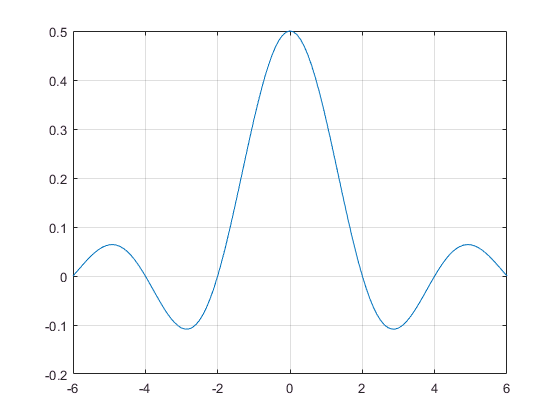

clear all, close all, clc;

% PARAMETERS
tau = 0.5;         % seconds
A = 1;            % Amplitude  in V

f = -6:0.1:6 ;     % freq vector


% FUNCTION
X_f = A*tau*sinc(f*tau);


% PLOT
figure()
plot(f,X_f),grid on

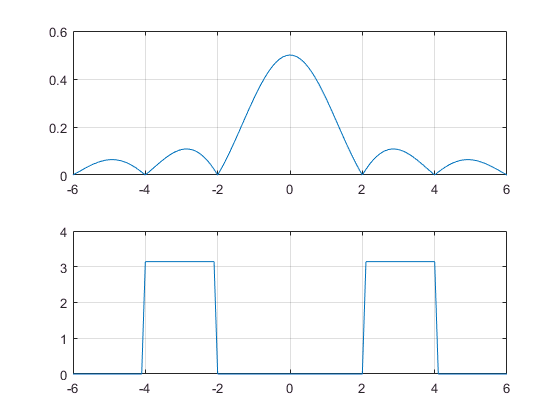


figure()
subplot(211),plot(f,abs(X_f)), grid on
subplot(212),plot(f,phase(X_f)),grid on

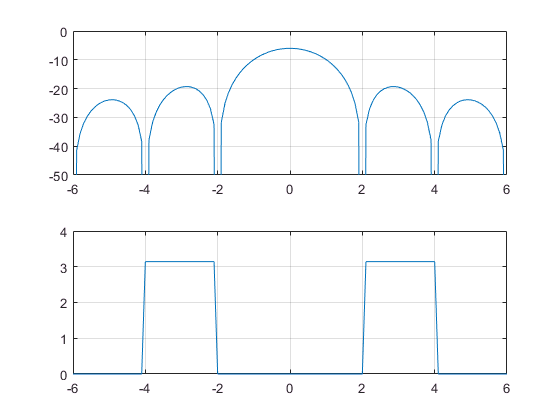


figure()
%subplot(211),plot(f,20*log10(abs(X_f))), grid on
subplot(211),plot(f,db(X_f)), grid on, ylim([-50 0])
subplot(212),plot(f,phase(X_f)),grid on

## Question 3-2

Based on example 3-2 (script chap-2 page-6), draw a sketch of the spectrum X(f) for the time functions: decaying exponential and Dirac impulse. 

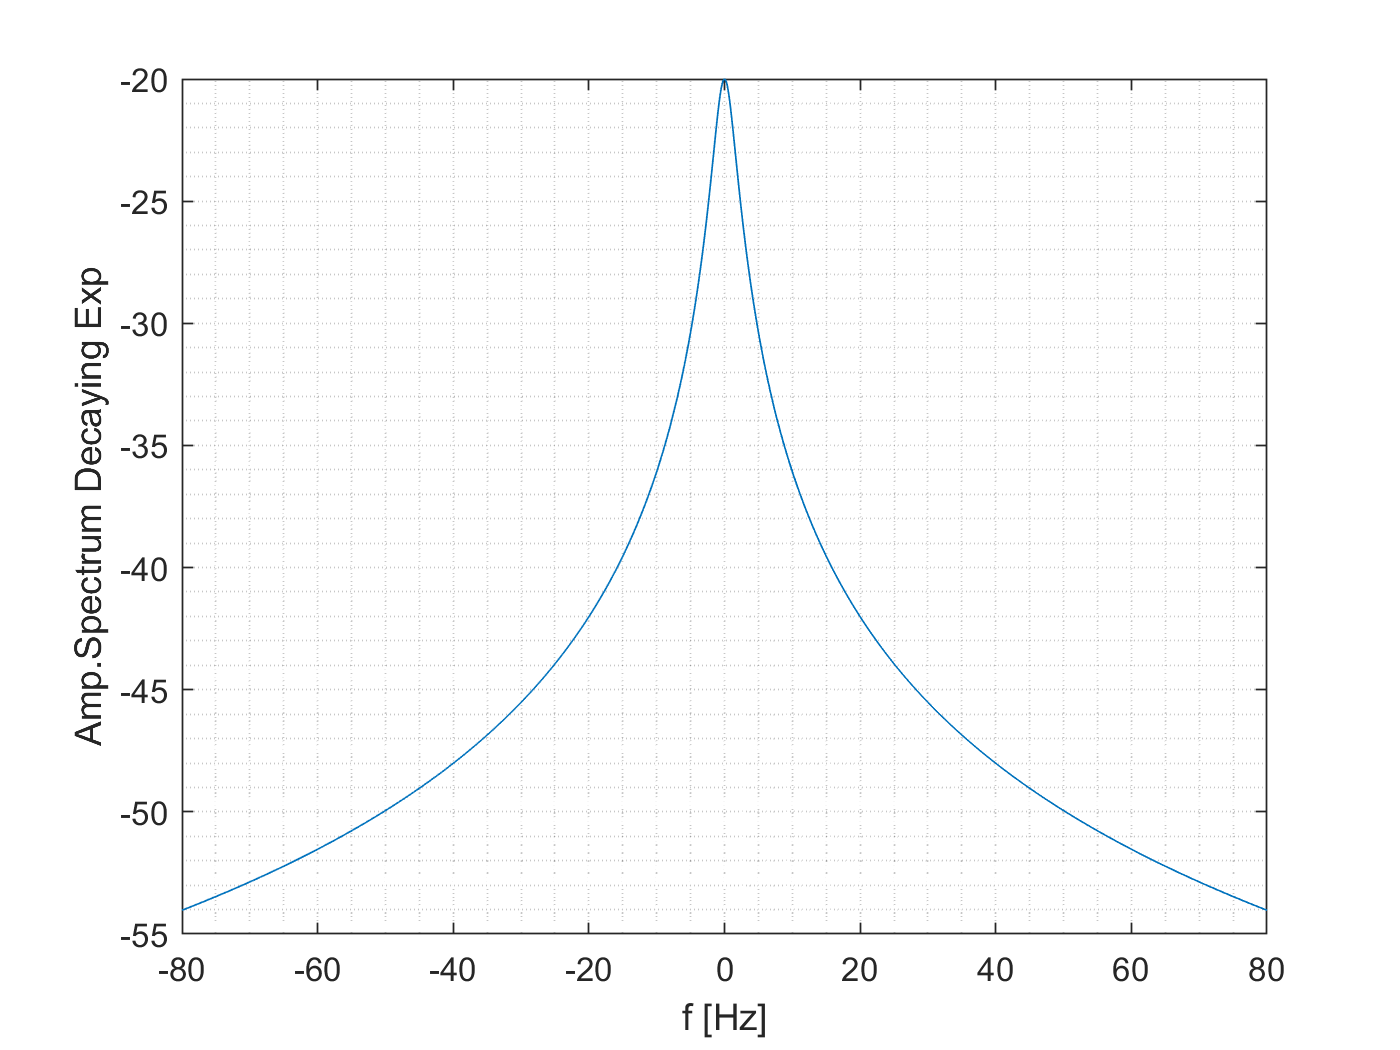

clear all, close all, clc

% PARAMETERS
Fmax = 80;  
f = -Fmax:Fmax/1e3:Fmax;    % frequency vector for plots of double sided spectrum

% FUNCTIONS
a = 10;
X_f_exp = 1./(a + j*2*pi*f);

X_f_imp = ones(1,length(f));

% PLOTS
figure()
plot(f,db(X_f_exp)), grid minor, xlabel('f [Hz]'), ylabel('Amp.Spectrum Decaying Exp')

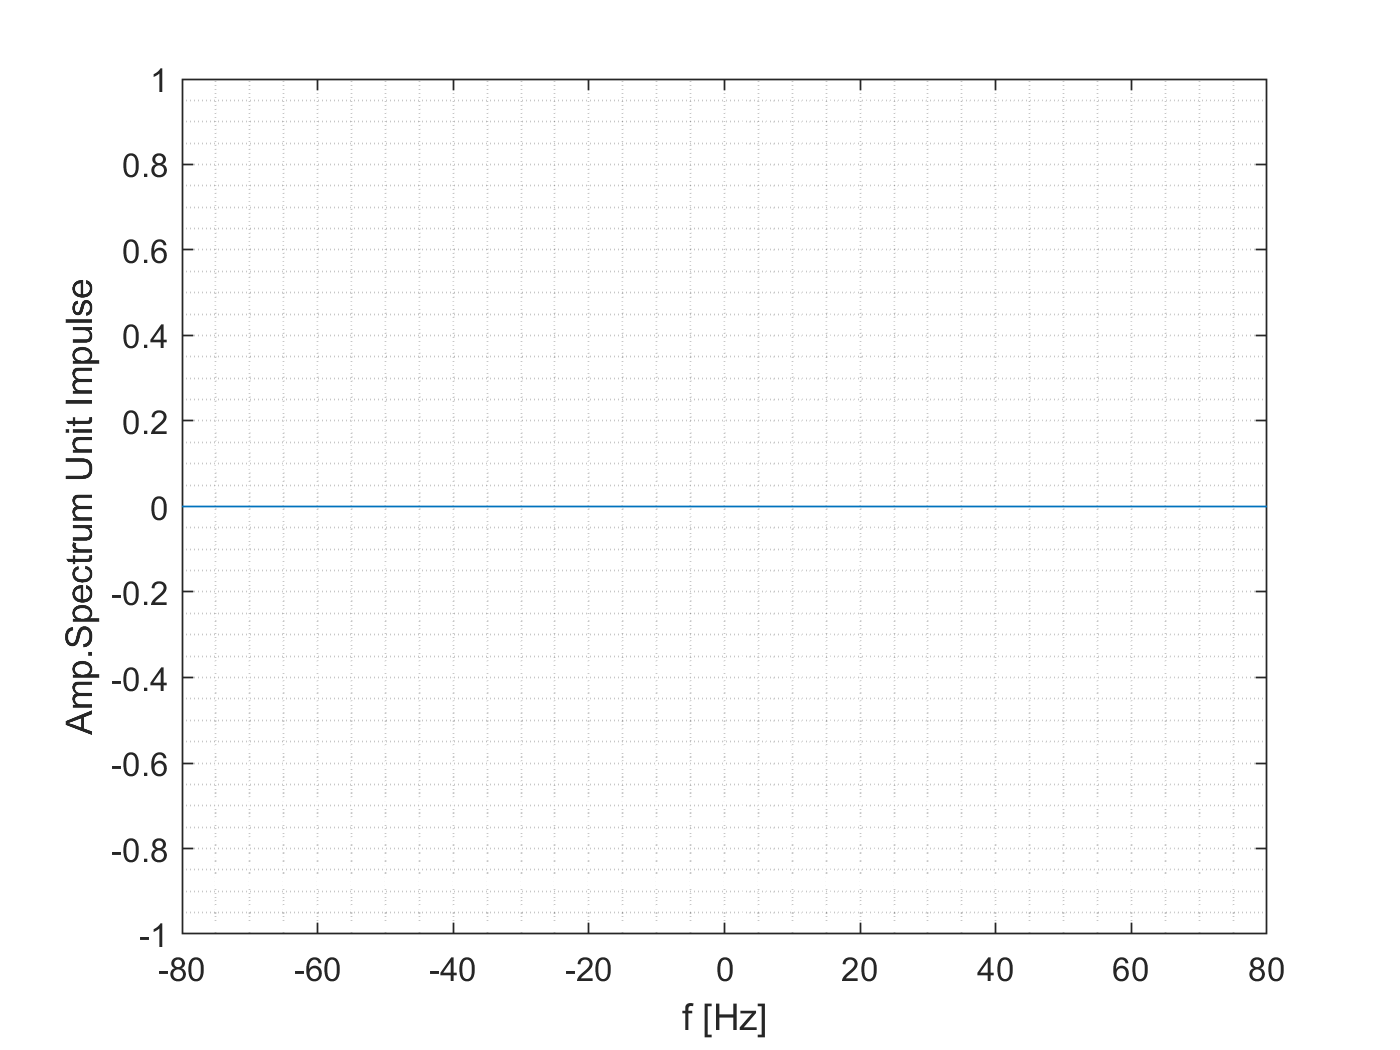


figure()
plot(f,db(X_f_imp)), grid minor, xlabel('f [Hz]'), ylabel('Amp.Spectrum Unit Impulse')

## Question 3-3

Use the properties above to calculate the Fourier transformation X(f) for the following time functions: 

- Unity step function :     

Approach: remember the step is the integral of the dirac impulse. Then use the transform of the impulse and the derivation property to get :


$$FT \{\sigma(t)\} =

 \frac{1}{j\omega} \cdot FT \{\delta(t)\} =  

 \frac{1}{j\omega} \cdot 1$$
        

- Constant DC-value :       

   Approach: remember the FT of the dirac impulse is a constant. Then use the duality property to get :


$$FT \{K \cdot 1 \} = K \cdot FT \{ 1 \} =

 K\cdot \delta(-f) =  K\cdot \delta(f)$$
        

- Cosine wave :     

  Approach: remember the Euler identity, and write the cosine as a sum of 2 complex exponentials. Then use the frequency shift property to get :


$$FT \{cos(2\pi f t)\} = 
\frac{1}{2} \cdot FT \{ e^{j2\pi ft} + e^{-j2\pi ft}   \} =

\frac{1}{2} \cdot ( \delta(f-f_0)+ \delta(f+f_0) )
$$
        

- Sine wave :      

 Approach: remember the Euler identity, and write the sine as a sum of 2 complex exponentials. Then use the frequency shift property to get :


$$FT \{sin(2\pi f t)\} = 
\frac{1}{2j} \cdot FT \{ e^{j2\pi ft} - e^{-j2\pi ft}   \} =

\frac{1}{2j} \cdot ( \delta(f-f_0) - \delta(f+f_0) )
$$
        

- Sinc function in time domain :    

 Approach: remember the FT of the square pulse is a sinc. Then use the duality property to get :


$$FT \{  A \cdot rect \left( \frac{t}{\tau} \right) \} = A\tau \cdot sinc(f\tau) $$
        

      therefore               


$$FT \{  A\tau \cdot sinc(t \cdot \tau) =  

A \cdot rect \left( \frac{-f}{\tau} \right) \} = 

A \cdot rect \left( \frac{f}{\tau} \right) \} $$
        

- Square function with width tau/2

Approach: remember the FT of the square pulse is a sinc. Then use the time-bandwidth property to get :


$$FT \{  A \cdot rect \left( \frac{t}{\tau} \right) \} = A\tau \cdot sinc(f\tau) $$
        

      therefore               


$$FT \{  A \cdot rect \left( \frac{t}{\tau/2} \right) \} = 

FT \{  A \cdot rect \left( \frac{2t}{\tau} \right) \} = 

\frac{A\tau}{2} \cdot sinc \left( \frac{f\tau}{2} \right) $$
  

Draw for each of the functions above a sketch of the signal in time and in frequency domain. 

% Solution: sketches by hand


## Question 3-4

Use the derivation property to calculate the transfer function of a passive RLC low pass filter (as you probably already know from electricity courses). Start your calculation with the differential equation of the RLC filter. Do you know how to determine the order of this low pass filter (LPF) ? 

Approach: start by applying the mesh rule and determining the differential equation


$$LC\ddot{y}(t) + RC\dot{y}(t) + y(t) = x(t) $$


Then applying the FT to both sides, and isolating the ratio:


$$\frac{Y(\omega)}{X(\omega)} = G(\omega) = 
G(j\omega) =

\frac{1}{LC(j\omega)^2 + RC(j\omega) + 1 }$$


## Question 3-5

Use the derivation property to calculate the complex impedance of a capacitor and of an inductance. Then use this result to calculate the transfer function of the passive RLC filter from the previous question.   

Approach: remember the relationship between current and voltage for a capacitor, and for an inductor

$i_C  (t) = C \cdot \frac{dv_C (t)}{dt}$                             ;          $v_L  (t) = L \cdot \frac{di_L (t)}{dt}$

Then applying the FT to both sides, and isolating the ratio:

$Z_C (j\omega) =

\frac{V_C(j\omega)}{I_C(j\omega)} = 

\frac{1}{(j\omega C)}$               ;           $Z_L (j\omega) =

\frac{V_L(j\omega)}{I_L(j\omega)} = 

{(j\omega L)}$

## Question 3-6

Given the channel width of the AM radio application, what is the allowed bandwidth for the information signal ? 

9e3/2    % because of double sideband after modulation which needs to fit within 9kHz
% in praxis probably less than that, because the filters limiting the bandwidth are not ideal.


## Example 3-4

Please check if time: 

probably useful to add intermediate steps of this example with some Matlab plots.

## Question 3-7

Re-calculate the spectrum of the comb function using the idea of shifting and repeating a non-periodic generating function. The generating function in this case is a single Dirac impulse.  

% hand sketches during lecture


## Example: Passive RC-Circuit

clear all, close all, clc;

% PARAMETERS
tau = 1e-3;                   % Time constant of 1ms
f = logspace(-3,+7,200);      % choose a frequency range where 1/tau is in the middle

% FUNCTION
G_f = 1./(1 + j*2*pi*f*tau );


% PLOT
figure()
subplot(211),semilogx(f,abs(G_f)),grid on, ylabel('Amp(G(f))')
subplot(212),semilogx(f,180/pi*phase(G_f)),grid on, ylabel('Phase(G(f))'),xlabel('f \rightarrow')

figure()
subplot(211),semilogx(f,db(G_f)),grid on, ylabel('Amp(G(f))')
subplot(212),semilogx(f,180/pi*phase(G_f)),grid on, ylabel('Phase(G(f))'),xlabel('f \rightarrow')

% TRY IT NOW WITH ANGULAR FREQUENCY
 w = logspace(-2,+6,200);
 G_w = 1./(1 + j*w*tau );

figure()
subplot(211),semilogx(w,db(G_w)),grid on, ylabel('Amp(G(w))')
subplot(212),semilogx(f,180/pi*phase(G_w)),grid on, ylabel('Phase(G(w))'),xlabel('w \rightarrow')
